clear
load('data.mat')

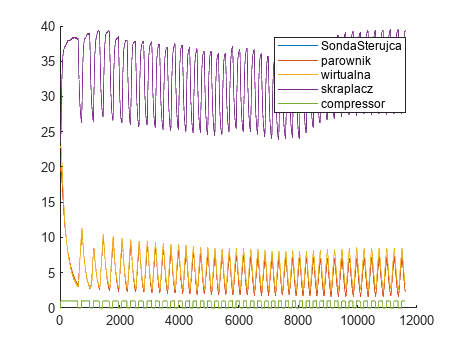

figure;hold on;
plot(data.SondaSterujca)
plot(data.parownik)
plot(data.wirtualna)
plot(data.skraplacz)
plot(data.compressor)
hold off

legend('SondaSterujca','parownik','wirtualna',...
'skraplacz','compressor')

Data filtering

% Find indices of NaN values
nan_indices = isnan(data.parownik);

% Exclude NaN values from the vector
parownik = data.parownik(~nan_indices);

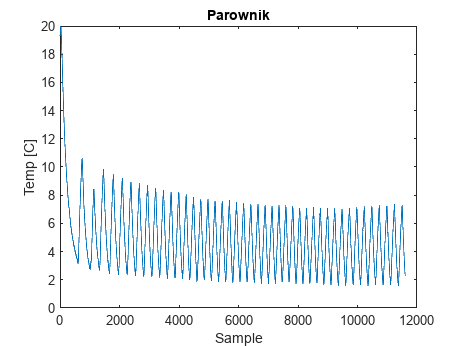

plot(parownik)
title('Parownik')
xlabel('Sample')
ylabel('Temp [C]')

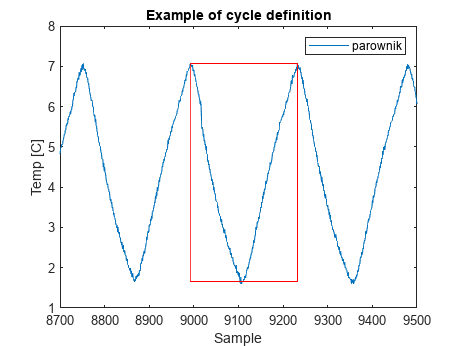

figure
window=8700:9500;
plot(window,parownik(window));hold on;


title('Example of cycle definition')
ylabel('Temp [C]')
xlabel('Sample')


a=8993;
b=9232;
c=mean(parownik(a:b));
rectangle('Position',[a,1.66,b-a,7.07-1.66],'EdgeColor','r')

legend('parownik')

hold off

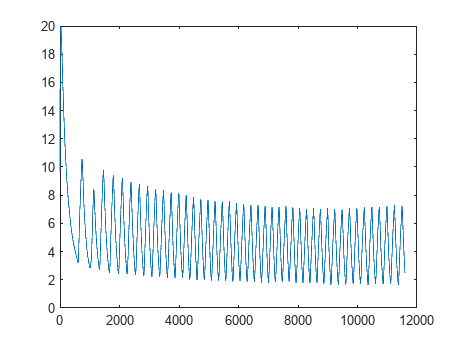

[x_filtered] = GetFilteredEvaporatorData(data);
n=length(x_filtered);
x=1:n;
plot(x,x_filtered);hold on;

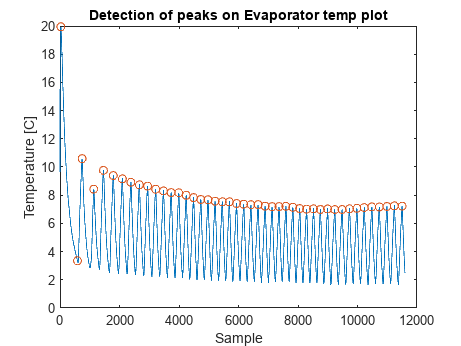

[pks,locs] = findpeaks(x_filtered);
plot(x(locs),pks,"o");hold off
title('Detection of peaks on Evaporator temp plot')
xlabel('Sample')
ylabel('Temperature [C]')

Features to be found:

1) length of cycle

2) max and min val in the cycle

3) mean

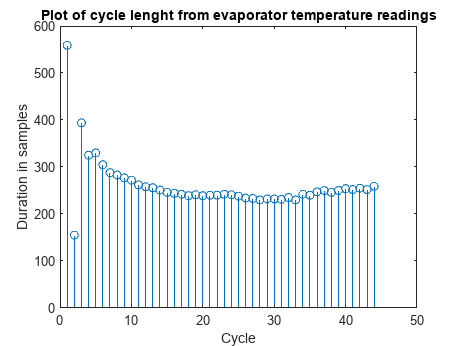

n_locs=length(locs);
f1=zeros(n_locs-1,1);
f3=f1;
f2=zeros(n_locs-1,2);
for i=1:n_locs-1
    f1(i)=locs(i+1)-locs(i);
    f2(i,:)=[max(x_filtered(locs(i):locs(i+1))),min(x_filtered(locs(i):locs(i+1)))];
    f3(i)=mean(x_filtered(locs(i):locs(i+1)));
end

stem(f1)
title('Plot of cycle lenght from evaporator temperature readings')
xlabel('Cycle')
ylabel('Duration in samples')

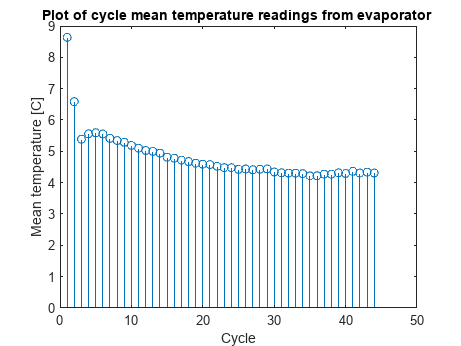

stem(f3)
title('Plot of cycle mean temperature readings from evaporator ')
xlabel('Cycle')
ylabel('Mean temperature [C]')